# Script to analyze PSC event data from pclamp

REMEMBER TO PULL AT THE BEGINNING OF EVERY SESSION AND PUSH AT THE END IF CODE CHANGES!!!!

## Analyze Synaptic currents

close all
clear

% Let's start by loading the matrix with the parameters (i.e. conductances)
% of zero error models found by the algorithm
Sham = Load_Params;
HFHI = Load_Params;

% PLOT FEATS% 
%% Savfe features for plotting
writetable(Sham.Feats.FeatsTable(:,'IV_Slope'),'ShamIVSlope.csv')
writetable(Sham.Feats.FeatsTable(:,'Rheo'),'ShamRheobase.csv')
writetable(HFHI.Feats.FeatsTable(:,'IV_Slope'),'HFHIIVSlope.csv')
writetable(HFHI.Feats.FeatsTable(:,'Rheo'),'HFHIRheobase.csv')

h =   1×3 Axes array:

    Axes    Axes    Axes


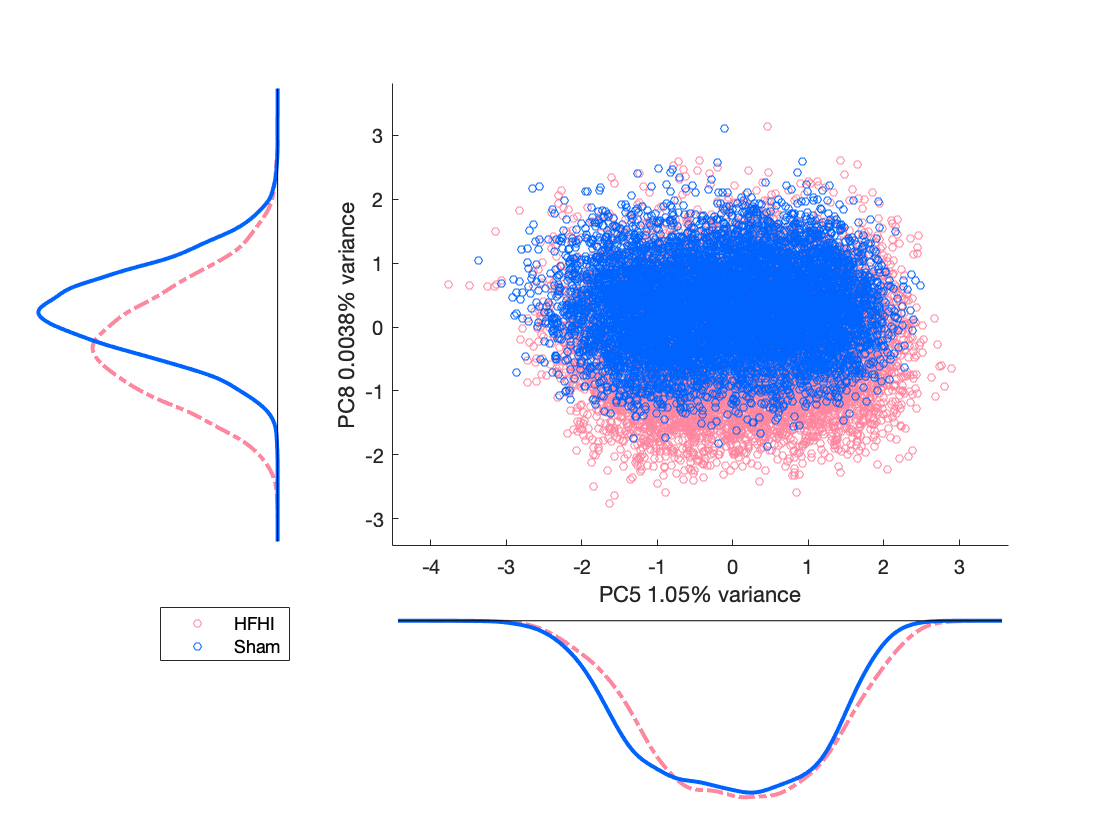


% RUN PCA% 
RunPCA(Sham,HFHI);  

h =   1×3 Axes array:

    Axes    Axes    Axes


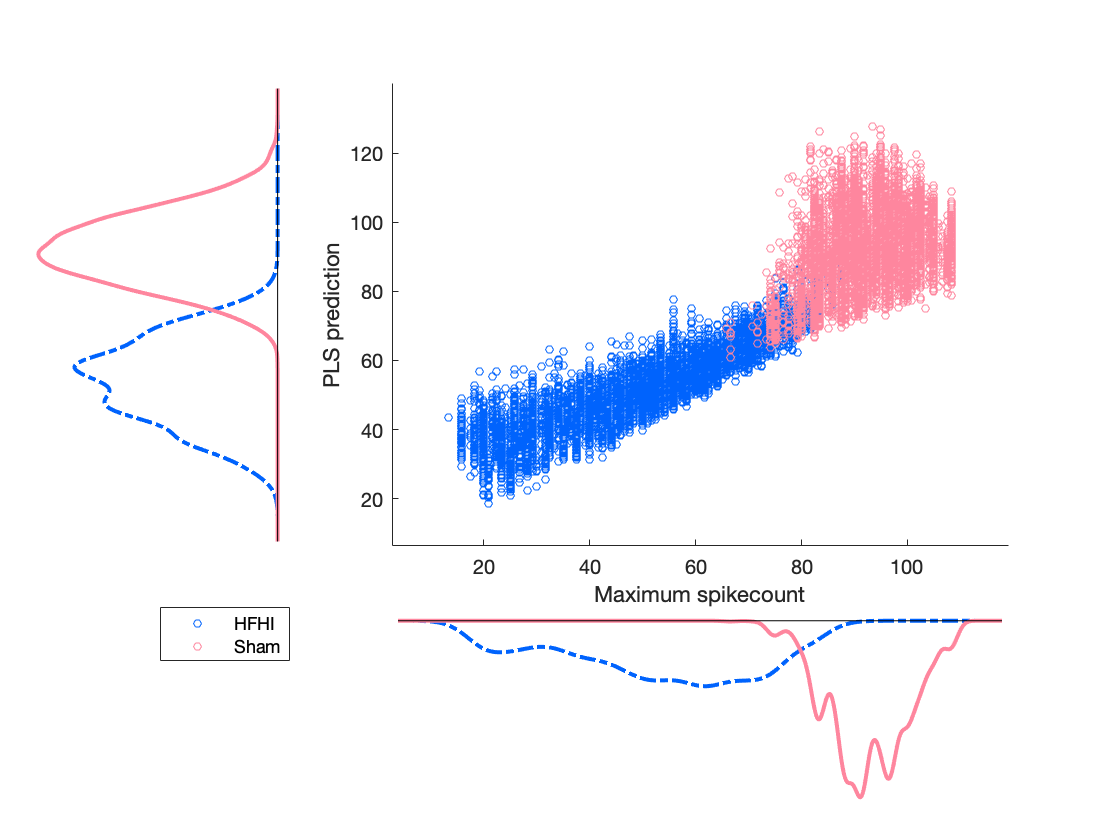

% RUN PSLR% 
RunPLSR(Sham,HFHI);

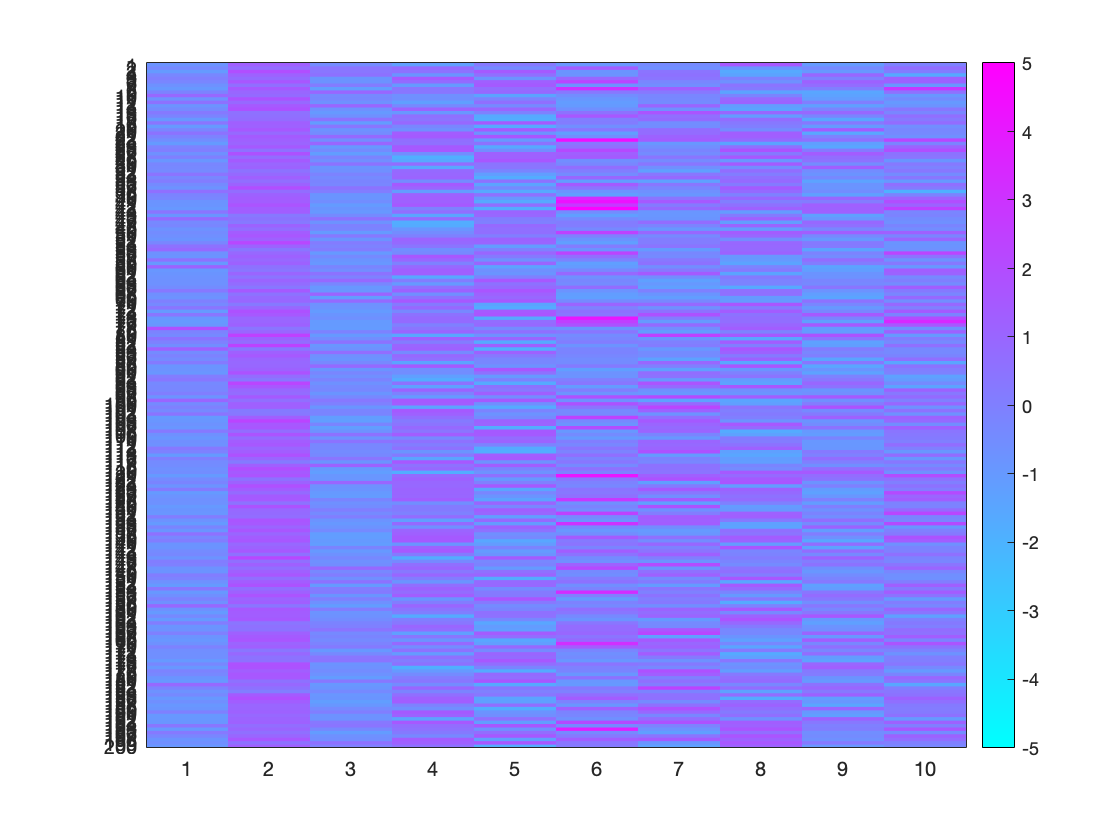

% Degeneracy 

AllParams = [Sham.Params.Params HFHI.Params.Params];
% Even though we took z scores for each group indivdiaully, we have to
% zscore them all together or else they'll both just be normally
% distributed within their own PCA 
AllZParams = zscore(AllParams');

ShamZParams = AllZParams(1:Sham.Length,:);
ShamVar = var(ShamZParams,0,1);
HFHIZParams = AllZParams(Sham.Length+1:end,:);
HFHIVar = var(HFHIZParams,0,1);

figure
heatmap(ShamZParams(1:200,:),'ColorMap',cool,'GridVisible','off',...
    'ColorLimits',[-5 5]);

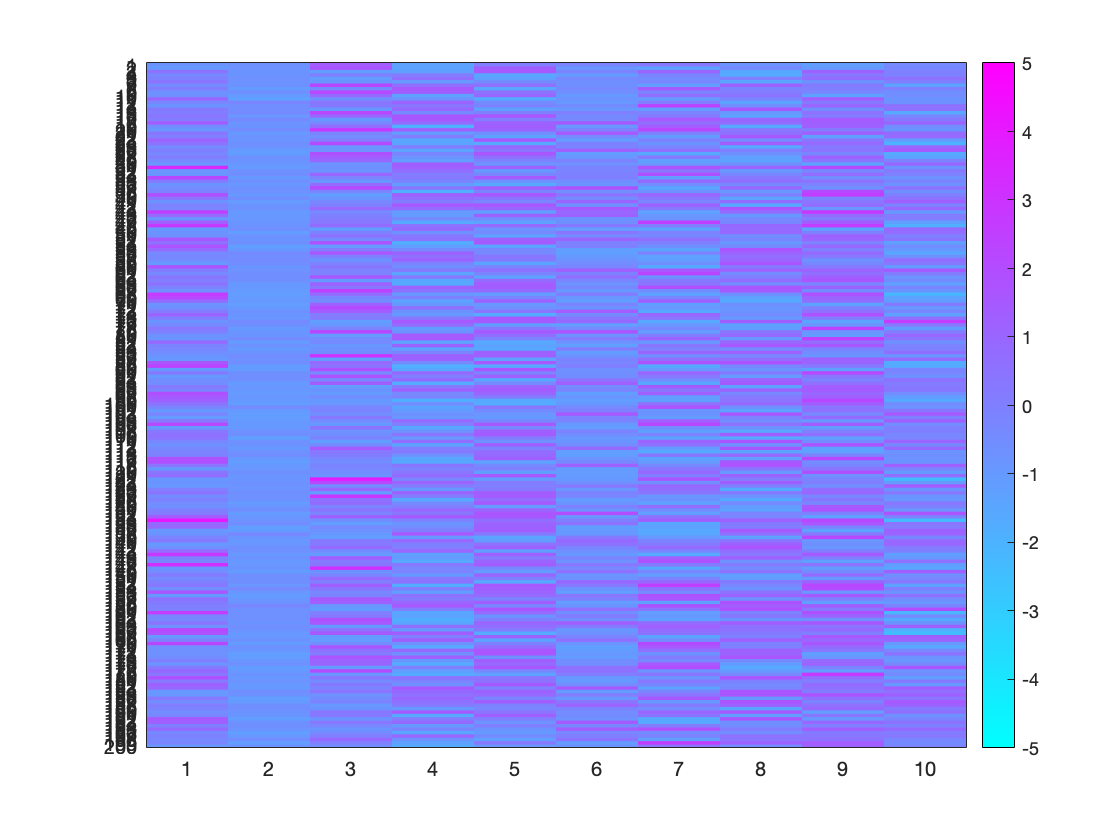

figure
heatmap(HFHIZParams(1:200,:),'ColorMap',cool,'GridVisible','off',...
    'ColorLimits',[-5 5]);